# Create Shadows

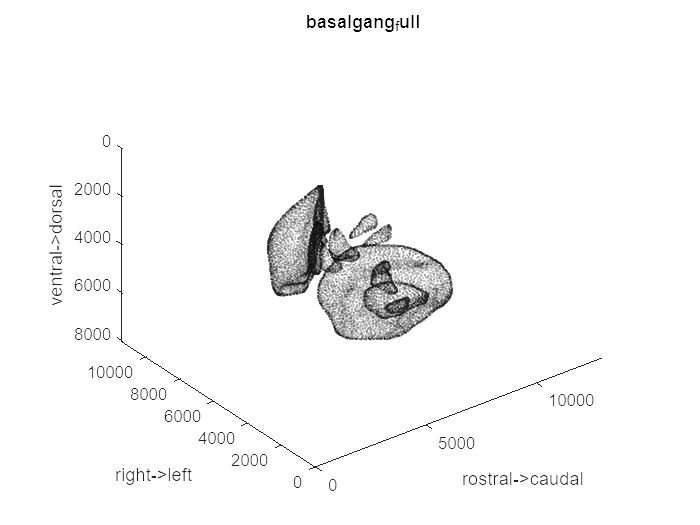

clear
clc
lookuptable
shadow = struct();
code = "basalgang_full";
home = pwd();

cd("C:\Users\davis\OneDrive\Desktop\heatmAPP_V2\shadows\" + code);
low_poly_table = readtable("low_poly.csv");
vertices_table = readtable("vertices.csv");
center_of_mass_table = readtable("center_of_mass.csv");

% Lowpoly __________________________________________________________________

% full
shadow.full.lowpoly = table2array(low_poly_table);
shadow.full.x_lowpoly = shadow.full.lowpoly(:,x);
shadow.full.y_lowpoly = shadow.full.lowpoly(:,y);
shadow.full.z_lowpoly = shadow.full.lowpoly(:,z);

% left
shadow.left.lowpoly = shadow.full.lowpoly(shadow.full.lowpoly(:,z) < 5700, :);
shadow.left.x_lowpoly = shadow.left.lowpoly(:,x);
shadow.left.y_lowpoly = shadow.left.lowpoly(:,y);
shadow.left.z_lowpoly = shadow.left.lowpoly(:,z);

% right
shadow.right.lowpoly = shadow.full.lowpoly(shadow.full.lowpoly(:,z) > 5700, :);
shadow.right.x_lowpoly = shadow.right.lowpoly(:,x);
shadow.right.y_lowpoly = shadow.right.lowpoly(:,y);
shadow.right.z_lowpoly = shadow.right.lowpoly(:,z);

% Vertices __________________________________________________________________

% full
shadow.full.vertices = table2array(vertices_table);
shadow.full.x_vertices = shadow.full.vertices(:,x);
shadow.full.y_vertices = shadow.full.vertices(:,y);
shadow.full.z_vertices = shadow.full.vertices(:,z);
shadow.full.xy = shadow.full.vertices(:,1:2);
shadow.full.yz = shadow.full.vertices(:,2:3);
shadow.full.xz = shadow.full.vertices(:,[1,3]);

% left
shadow.left.vertices = shadow.full.vertices(shadow.full.vertices(:,z) < 5700, :);
shadow.left.x_vertices = shadow.left.vertices(:,x);
shadow.left.y_vertices = shadow.left.vertices(:,y);
shadow.left.z_vertices = shadow.left.vertices(:,z);
shadow.left.xy = shadow.left.vertices(:,1:2);
shadow.left.yz = shadow.left.vertices(:,2:3);
shadow.left.xz = shadow.left.vertices(:,[1,3]);

% right
shadow.right.vertices = shadow.full.vertices(shadow.full.vertices(:,z) > 5700, :);
shadow.right.x_vertices = shadow.right.vertices(:,x);
shadow.right.y_vertices = shadow.right.vertices(:,y);
shadow.right.z_vertices = shadow.right.vertices(:,z);
shadow.right.xy = shadow.right.vertices(:,1:2);
shadow.right.yz = shadow.right.vertices(:,2:3);
shadow.right.xz = shadow.right.vertices(:,[1,3]);

% Bounds ___________________________________________________________________

% full
shadow.full.x_bounds = round([min(shadow.full.x_vertices), max(shadow.full.x_vertices)],0);
shadow.full.y_bounds = round([min(shadow.full.y_vertices), max(shadow.full.y_vertices)],0);
shadow.full.z_bounds = round([min(shadow.full.z_vertices), max(shadow.full.z_vertices)],0);

% left
shadow.left.x_bounds = round([min(shadow.left.x_vertices), max(shadow.left.x_vertices)],0);
shadow.left.y_bounds = round([min(shadow.left.y_vertices), max(shadow.left.y_vertices)],0);
shadow.left.z_bounds = round([min(shadow.left.z_vertices), max(shadow.left.z_vertices)],0);

% right
shadow.right.x_bounds = round([min(shadow.right.x_vertices), max(shadow.right.x_vertices)],0);
shadow.right.y_bounds = round([min(shadow.right.y_vertices), max(shadow.right.y_vertices)],0);
shadow.right.z_bounds = round([min(shadow.right.z_vertices), max(shadow.right.z_vertices)],0);

% Range ____________________________________________________________________________
shadow.full.x_range = diff(shadow.full.x_bounds);
shadow.full.y_range = diff(shadow.full.y_bounds);
shadow.full.z_range = diff(shadow.full.z_bounds);

shadow.left.x_range = diff(shadow.left.x_bounds);
shadow.left.y_range = diff(shadow.left.y_bounds);
shadow.left.z_range = diff(shadow.left.z_bounds);

shadow.right.x_range = diff(shadow.right.x_bounds);
shadow.right.y_range = diff(shadow.right.y_bounds);
shadow.right.z_range = diff(shadow.right.z_bounds);

% Center of Mass ___________________________________________________________________
shadow.center_of_mass = table2array(center_of_mass_table);

figure;
scatter3( ...
    shadow.full.x_lowpoly, ...
    shadow.full.z_lowpoly, ...
    shadow.full.y_lowpoly, ...
    1, ...
    'filled', ...
    'k', ...
    'MarkerFaceAlpha', .5 ... 
);
hold on
scatter3( ...
    shadow.left.x_lowpoly, ...
    shadow.left.z_lowpoly, ...
    shadow.left.y_lowpoly, ...
    3, ...
    'filled', ...
    'k', ...
    'MarkerFaceAlpha', 0.2 ... 
);
scatter3( ...
    shadow.right.x_lowpoly, ...
    shadow.right.z_lowpoly, ...
    shadow.right.y_lowpoly, ...
    3, ...
    'filled', ...
    'k', ...
    'MarkerFaceAlpha', 0.2 ... 
);
% scatter3( ...
%     shadow.center_of_mass(:,x), ...
%     shadow.center_of_mass(:,z), ...
%     shadow.center_of_mass(:,y), ...
%     20, ...
%     'filled', ...
%     'k', ...
%     'MarkerFaceAlpha', 0.2 ... 
% );
set(gca, 'ZDir', 'reverse');
xlabel('rostral->caudal'); xlim([0, fixed.xmax]); %xticks([0, fixed.xmax]); xticks([0 shadow.full.x_bounds]);
ylabel('right->left'); ylim([0, fixed.zmax]); %yticks([0, fixed.zmax]); yticks([0 shadow.left.z_bounds shadow.right.z_bounds]);
zlabel('ventral->dorsal'); zlim([0, fixed.ymax]); %zticks([0, fixed.ymax]); zticks([0 shadow.full.y_bounds]);
pbaspect([1 (fixed.zmax/fixed.xmax) (fixed.ymax/fixed.xmax)]);
title(code)
grid off
hold off


save("shadow.mat", "shadow")
disp("Saved Shadow")

Saved Shadow



clear bounds_table center_of_mass_table vertices_table low_poly_table

cd(home);
clear
clc